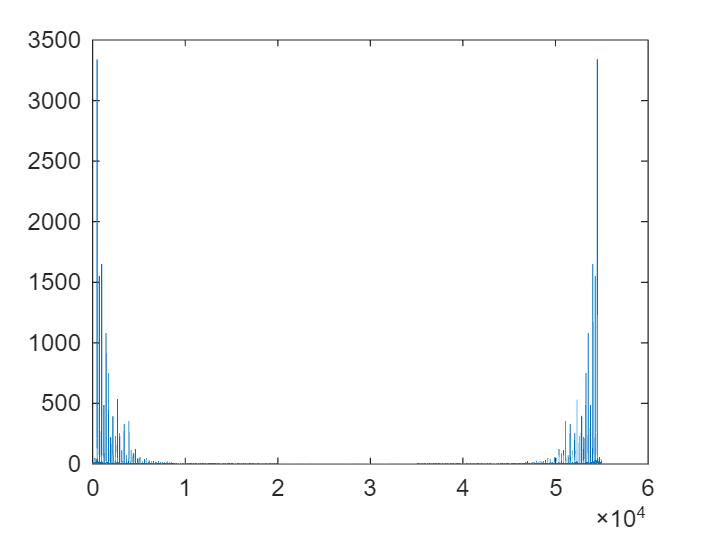

clear;
load("Violine_example.mat");
%sound(example, Fs_example);

X = fft(example);
plot(0:length(X)-1, abs(X));

[maxValue, maxIndex] = max(abs(X));
disp("maxValue = " + maxValue);

maxValue = 3341.9487


disp("maxIndex = " + (maxIndex-1));

maxIndex = 487



global Fs lengthOf1 m c_m;
Fs = 44100; % Samplerate
lengthOf1 = 0.8; % Dauer einer "ganzen Note" in Sekunden
m = [1 2 3 4 6 8 10 12 14 16 18 20 24]; % Vektor der implementierten Obertöne
c_m = zeros(1, length(m));
mainVolume = 0.1;

c_1 = -6.6981e-05+1.338e-05i
c_2 = -5.7454e-05+3.0476e-06i
c_3 = -8.8549e-05-8.2996e-05i
c_4 = -0.00015895-2.2688e-05i
c_6 = -5.4748e-05+2.1446e-05i
c_8 = -0.00018358+0.00010551i
c_10 = 0.00023961+0.00032309i
c_12 = -8.4822e-05-8.1284e-05i
c_14 = -0.00018853+0.00034779i
c_16 = -0.00027331+0.0001141i
c_18 = -0.00019141+2.2575e-05i
c_20 = -0.00014601+0.00013021i
c_24 = -6.8515e-05-8.7892e-05i



n = 0:length(example)-1;
for i = 1 : length(m)
    e = exp(-1 .* 1i .* 2 .* pi .* ((m(1,i) .* n) ./ length(example)));
    c_m(1, i) = (1 ./ length(example)) .* sum(transpose(example) .* e);
    disp("c_" + m(1,i) + " = " + c_m(1, i));
end
